% Exercise Part A - Split into three parts
% Setup and recording
Fs = 16000;
nBits = 16;
nChannels = 1;
recObj = audiorecorder (Fs, nBits, nChannels);

% Saving recorded object
getaudiodata(recObj);
audiowrite("audio.wav", getaudiodata(recObj), Fs);

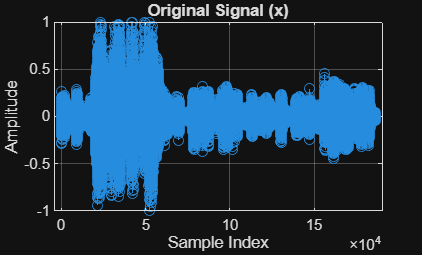

% Obtaining data
[x, F] = audioread("audio.wav");

% Part B - Digital upsampling
U = 4;
isr_x = upsample(x, U);

% Create stem plots of x and isr_x in two separate figures.
% Original and IncreasedSR
figure('Name', 'Original');
stem(x);
title('Original Signal (x)');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

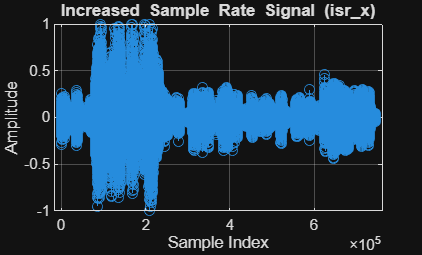


figure('Name', 'IncreasedSR');
stem(isr_x);
title('Increased Sample Rate Signal (isr\_x)');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

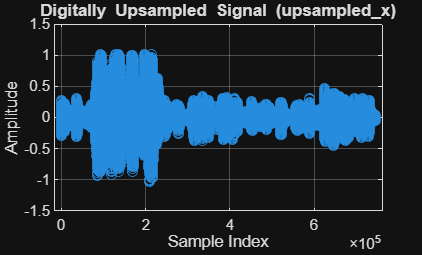


% Load non-ideal interpolation filter 
load('filter1.mat', 'b');
upsampled_x = filter(b, 1, isr_x);

% Create stem plot of upsampled_x.
figure('Name', 'Upsampled');
stem(upsampled_x);
title('Digitally Upsampled Signal (upsampled\_x)');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

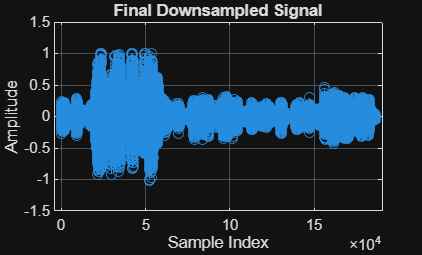

% Part C: Digital Downsampling

% Load the anti-aliasing filter coefficients
load('filter2.mat', 'b'); 

% Pass the upsampled signal through the digital anti-aliasing filter.
filtered_upsampled_x = filter(b, 1, upsampled_x); 

D = 4;

% Downsampling
downsampled_upsampled_x = downsample(filtered_upsampled_x, D); 

% Create stem plot of the final signal.
figure('Name', 'Final Downsampled');
stem(downsampled_upsampled_x);
title('Final Downsampled Signal');
xlabel('Sample Index');
ylabel('Amplitude');
2grid on;